k_e = 0.3824

k_e = 0.3824

k_m = 0.3824

k_m = 0.3824

J = 0.0019

J = 0.0019

R = 4.6296

R = 4.6296


t = 0.0:0.01:0.5;
y_ir = (k_m / (R * J)) * exp(- (k_e * k_m) / (R * J) * t)

y_ir =    43.4731   36.8149   31.1764   26.4015   22.3579   18.9336   16.0337   13.5780   11.4985    9.7374    8.2460    6.9831    5.9136    5.0079    4.2409    3.5913    3.0413    2.5755    2.1810    1.8470    1.5641    1.3246    1.1217    0.9499    0.8044    0.6812    0.5769    0.4885    0.4137    0.3503    0.2967    0.2512    0.2128    0.1802    0.1526    0.1292    0.1094    0.0927    0.0785    0.0665    0.0563    0.0477    0.0404    0.0342    0.0289    0.0245    0.0208    0.0176    0.0149    0.0126


y_sr = (1 / k_e) * (1 - exp(- (k_e * k_m) / (R * J) * t))

y_sr =          0    0.4005    0.7397    1.0269    1.2702    1.4761    1.6506    1.7983    1.9234    2.0293    2.1190    2.1950    2.2593    2.3138    2.3600    2.3990    2.4321    2.4601    2.4839    2.5040    2.5210    2.5354    2.5476    2.5579    2.5667    2.5741    2.5804    2.5857    2.5902    2.5940    2.5972    2.5999    2.6023    2.6042    2.6059    2.6073    2.6085    2.6095    2.6103    2.6111    2.6117    2.6122    2.6126    2.6130    2.6133    2.6136    2.6138    2.6140    2.6142    2.6143



y_c = sign(t + 0.1) / k_e

y_c =     2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151    2.6151



w = 0.0:0.01:0.5

w =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


%A = k_m / sqrt((k_m * k_e) * (k_m * k_e)  + (J * R * w ) * (J * R * w ) )
phi = atan(- (w * R * J) / (k_e * k_m))

phi =          0   -0.0006   -0.0012   -0.0018   -0.0024   -0.0030   -0.0036   -0.0042   -0.0048   -0.0054   -0.0060   -0.0066   -0.0072   -0.0078   -0.0084   -0.0090   -0.0096   -0.0102   -0.0108   -0.0114   -0.0120   -0.0126   -0.0132   -0.0138   -0.0144   -0.0150   -0.0156   -0.0162   -0.0168   -0.0174   -0.0180   -0.0186   -0.0192   -0.0198   -0.0204   -0.0211   -0.0217   -0.0223   -0.0229   -0.0235   -0.0241   -0.0247   -0.0253   -0.0259   -0.0265   -0.0271   -0.0277   -0.0283   -0.0289   -0.0295


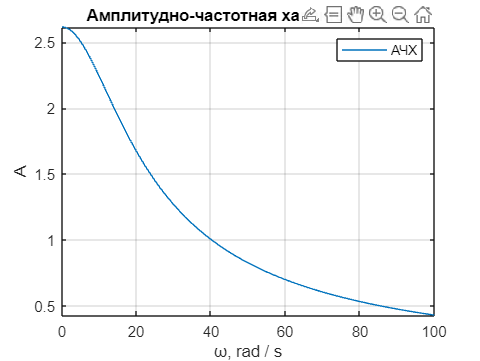


%plot(w, A, 'DisplayName', 'АЧХ')

%plot(t, y_sr)

ezplot ('(0.3824 / sqrt( 0.3824 * 0.3824 * 0.3824 * 0.3824 + (0.0019 * 4.6296 * x ) * (0.0019 * 4.6296 * x ))) ', [0 100])
axis tight


%yline(1 / k_e, '-.')

grid()
title('Амплитудно-частотная характеристика')
%title('Переходная функция для ДПТ')
legend('АЧХ')
ylabel('A')
xlabel('ω, rad / s')